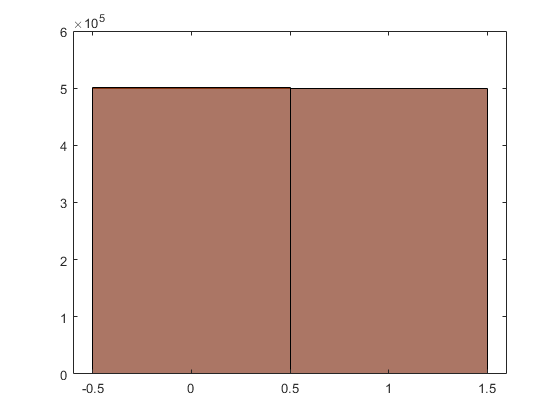

% script to test the scaling of the transition matrix

D_TM = [0.9 0.1; 0.3 0.7];
scaling_factor = 5;

% scaling
D_TM_scale = D_TM^(1/5);
% normalization
D_TM_scale = D_TM_scale ./ sum(D_TM_scale,1);

% compute markov chain unscaled
mc = dtmc(D_TM);
out = simulate(mc, 1e6, 'X0',[1 0]);
out = out >= 1.5;

% compute markov chain scaled
mc_scale = dtmc(D_TM_scale);
out_scale = simulate(mc_scale, 1e6*scaling_factor, 'X0',[1 0]);
out_scale = sum(reshape(out_scale(1:end-1),[scaling_factor (numel(out_scale)-1)/scaling_factor]),1) >= 1.5*scaling_factor;

% plot histogram individual components
figure
histogram(out)
hold on
histogram(out_scale)